# Homework 7

Thor Andreassen

10/27/22

## Clearing

clear
close all
clc


## constants

E=10*10^6;

mu_F=100;
mu_L=48;
mu_b=2;
mu_h=1.25;

cov_F=.1;
cov_L=.05;
cov_b=.05;
cov_h=.05;


## standard deviations

sigma_F=cov_F*mu_F;
sigma_L=cov_L*mu_L;
sigma_b=cov_b*mu_b;
sigma_h=cov_h*mu_h;


## model equation

syms b h F L
I= (b*h^3)/12;
delta=(F*L^3)/(3*E*I);
delta_func=matlabFunction(delta,'Vars',{[F;L;b;h]})

delta_func = function_handle with value:
    @(in1)(in1(1,:).*in1(2,:).^3.*1.0./in1(4,:).^3)./(in1(3,:).*2.5e+6)


delta_a=1.78;
limit_func=@(in1) delta_a-delta_func(in1);


## create distributions

F_model=makedist('Normal',mu_F,sigma_F);
L_model=makedist('Normal',mu_L,sigma_L);
b_model=makedist('Normal',mu_b,sigma_b);
h_model=makedist('Normal',mu_h,sigma_h);


## Monte Carlo Analysis

num_mag=6

num_mag = 6

tic1=tic();
num_trials=10^num_mag;

MC_inputs=zeros(num_trials,4);
MC_outputs=zeros(num_trials,1);

for count_trial=1:num_trials
    MC_inputs(count_trial,1)=random(F_model);
    MC_inputs(count_trial,2)=random(L_model);
    MC_inputs(count_trial,3)=random(b_model);
    MC_inputs(count_trial,4)=random(h_model);
    MC_outputs(count_trial)=delta_func(MC_inputs(count_trial,:)');
end
MC_time=toc(tic1);

## Part a monte carlo

conv_test=10.^[1:num_mag];
for count_MC_conv=1:length(conv_test)
    current_num=conv_test(count_MC_conv);
    MC_allow(count_MC_conv)=sum(MC_outputs(1:current_num)>delta_a)/current_num;
end
MC_allow

MC_allow =          0    0.0200    0.0310    0.0269    0.0282    0.0285


## Part a Form 2

models=[F_model;L_model;b_model;h_model];
mus=[mu_F;mu_L;mu_b;mu_h];
tol=.00001

tol = 1.0000e-05

limit_state=delta_a;
[Beta,Pf,alphas,X]=form2(delta_func,models,mus,limit_state,tol)

Beta = 1.8922

Pf = 0.0292

alphas =    -0.3898
   -0.5943
    0.2136
    0.6703


X =   107.3750
   50.6990
    1.9596
    1.1707


## Part b Monte Carlo Error prediction

conf_int=0.95;
bounds_val=norminv(conf_int+(1-conf_int)/2);
MC_allow_std=sqrt(((1-MC_allow(end))*MC_allow(end))/conv_test(end));
MC_allow_bounds=[-bounds_val*MC_allow_std,bounds_val*MC_allow_std]

MC_allow_bounds = 	1.0e+-3 *

   -0.3259    0.3259


MC_error_percent=sqrt((1-MC_allow(end))/(MC_allow(end)*conv_test(end)))*200

MC_error_percent = 1.1684

## Part C Monte Carlo Correlations

corr_vals=corrcoef([MC_inputs,delta_a-MC_outputs]);
F_corr=corr_vals(end,1);
L_corr=corr_vals(end,2);
b_corr=corr_vals(end,3);
h_corr=corr_vals(end,4);
table(F_corr,L_corr,b_corr,h_corr)

ans = 1×4 table
     F_corr      L_corr     b_corr     h_corr 
    ________    ________    _______    _______

    -0.40989    -0.61169    0.20475    0.62169


## Part C Monte Carlo Sensitivity Plots

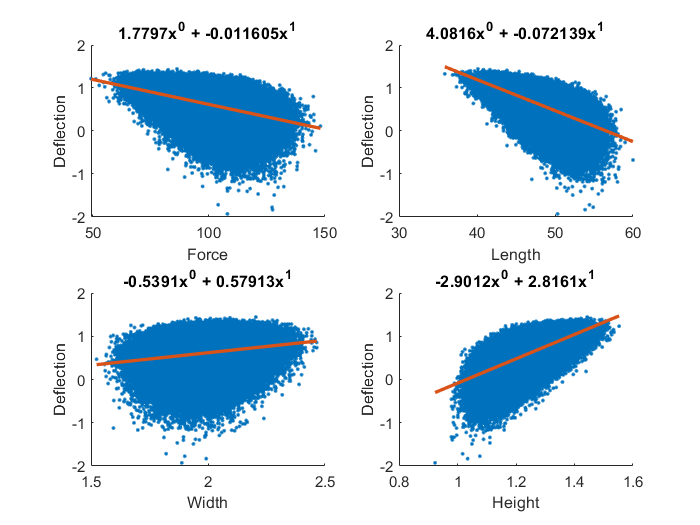

figure()
subplot(2,2,1)
plotTrendLine(MC_inputs(:,1),delta_a-MC_outputs,1);
xlabel('Force');
ylabel('Deflection')

subplot(2,2,2)
plotTrendLine(MC_inputs(:,2),delta_a-MC_outputs,1);
xlabel('Length');
ylabel('Deflection')

subplot(2,2,3)
plotTrendLine(MC_inputs(:,3),delta_a-MC_outputs,1);
xlabel('Width');
ylabel('Deflection')

subplot(2,2,4)
plotTrendLine(MC_inputs(:,4),delta_a-MC_outputs,1);
xlabel('Height');
ylabel('Deflection')

## Part d Form2 Importance factors

alphas

alphas =    -0.3898
   -0.5943
    0.2136
    0.6703


## Part e Monte Carlo

MC_outputs_percentiles=quantile(MC_outputs,[.05,.95])

MC_outputs_percentiles =     0.7576    1.6726


[Zamv]=AMV(delta_func,models,mus,[.05,.95],tol,0);
Zamv.Z

ans =     0.7614    1.6770


## FORM/AMV/MC CDF

MC_p=[.001,.01,.05,.1,.2,.25];
MC_p=[MC_p,.5,fliplr(1-MC_p)];
MC_X=quantile(MC_outputs,MC_p);

tic1=tic();
FORM_X=MC_X;
for count_test=1:length(FORM_X)
    [~,FORM_p(count_test),~,~]=form2(delta_func,models,mus,FORM_X(count_test),tol);
end
FORM_time=toc(tic1);

FORM_dir=find(diff(FORM_p(1:end-1))>0 & diff(FORM_p(2:end)) < 0)+1;
FORM_p(FORM_dir+1:end)=1-FORM_p(FORM_dir+1:end);


tic1=tic();
[Zamv]=AMV(delta_func,models,mus,MC_p,tol,0);
AMV_p=Zamv.probabilities;
AMV_X=Zamv.Z;
AMV_time=toc(tic1);

## PLOT CDF OF AMV/FORM/MC

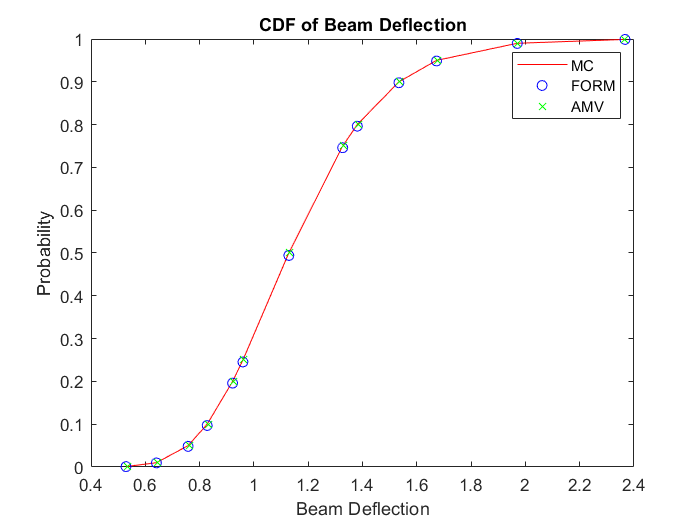

figure()
plot(MC_X,MC_p,'r');
hold on
plot(FORM_X,FORM_p,'bo');
plot(AMV_X,AMV_p,'gx');
legend('MC','FORM','AMV')
title('CDF of Beam Deflection')
xlabel('Beam Deflection')
ylabel('Probability')


table(MC_time,FORM_time,AMV_time)

ans = 1×3 table
    MC_time    FORM_time    AMV_time
    _______    _________    ________

    90.355      0.12251     0.019356
